# BMS Algorithms

## Brief Description

The Battery Management System software is made up of following software components:

- State Machine (Top Level Supervisory Logic)

- Current and Power Limit Calculations

- Fault Detection Logic

- Charge Management

- Contactor Management

- SOC Estimation

- Cell Balancing

 The BMS aims at:

- balancing state of charge of battery cells;

- making sure that the temperature of battery cells stays within desired values (e.g., fault generated when temperature is too hot or too cold);

- making sure that the current through the battery stays within desired values (e.g., fault generated when current is too high);

- making sure that the voltage of the battery is equal to that of the charger while charging, and to that of the load while giving power, so as to avoid dangerous spikes;

- connecting the battery to the load or the charger based on the desired command request.

### State Machine

The three main functionalities of the state machine are:

- It’s the main control unit that decides how to open and close the switching devices in the pre-charge circuit based on the request of charging or providing power.

- It sends a request of positive constant current to the charger when the battery needs to be charged and the SOC is low (CC mode). Once the voltage at the terminals of the battery has achieved a certain desired value and the SOC has increased, the remaining charge is done in constant voltage mode (CV mode), i.e., the aim is to keep the voltage at the terminals of the battery fixed and the requested charging current will exponentially converge to 0. In the model, the charger is modelled with an ideal controlled current source, therefore we can assume that the charging current requested by the state machine is equal to the current provided by the charger.

- It monitors possible faults and opens circuits when this happens so as to avoid dangerous situations.

### SOC Estimation

It estimates the state of charge of all the cells starting from current, cell voltage, and temperature.

### Balancing Logic

It’s the control unit that aims at balancing the state of charge of all the cells by appropriately opening and closing the switching devices in the cell monitoring unit. The technique used is passive balancing.

Balancing is fundamental to prevent early battery degradation, but also to make sure that we have good performance from the battery because:

- the maximum cell voltage limits how much current we can inject to charge the battery;

- the minimum cell voltage limits how much current we can draw from the battery.

## Closed Loop Simulation of BMS Algorithms

[Open Test Harness](matlab:open_system('BMS_Software_Harness1.slx'))

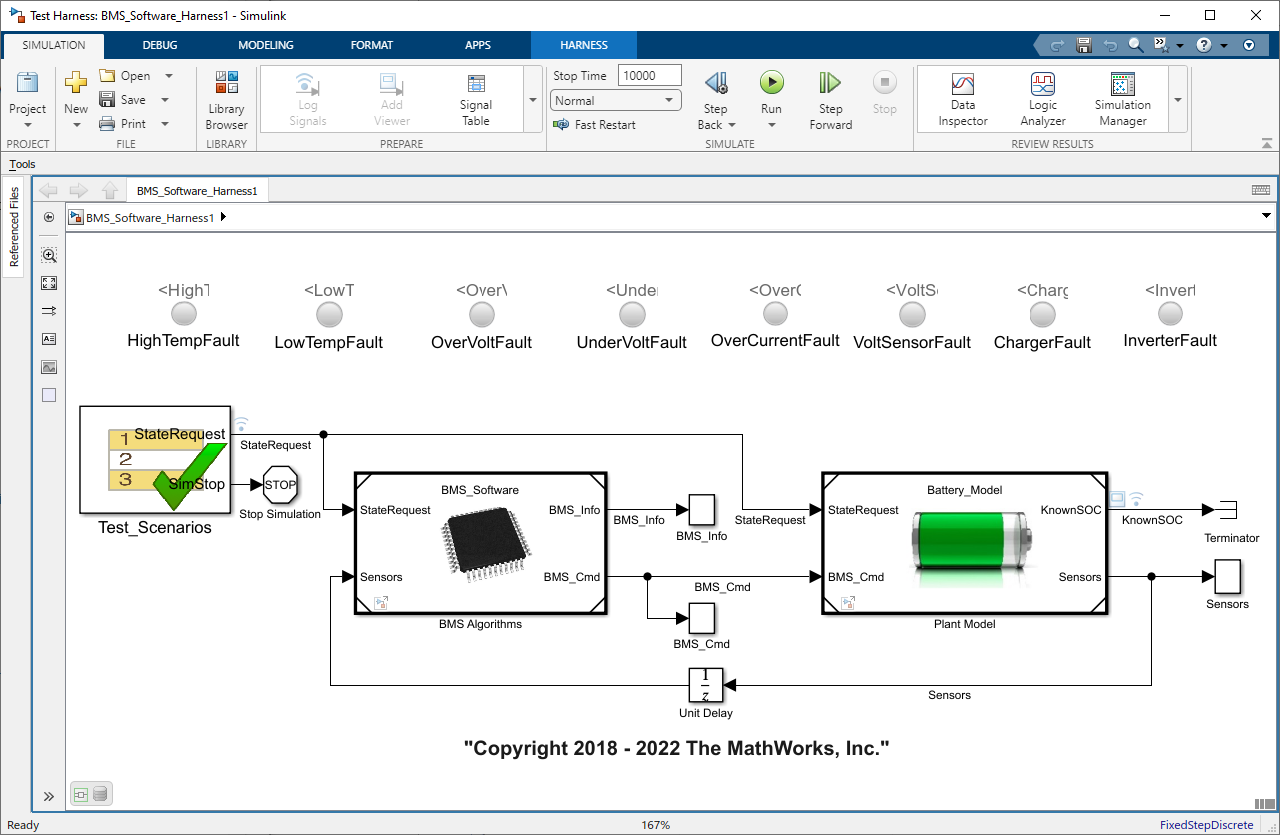

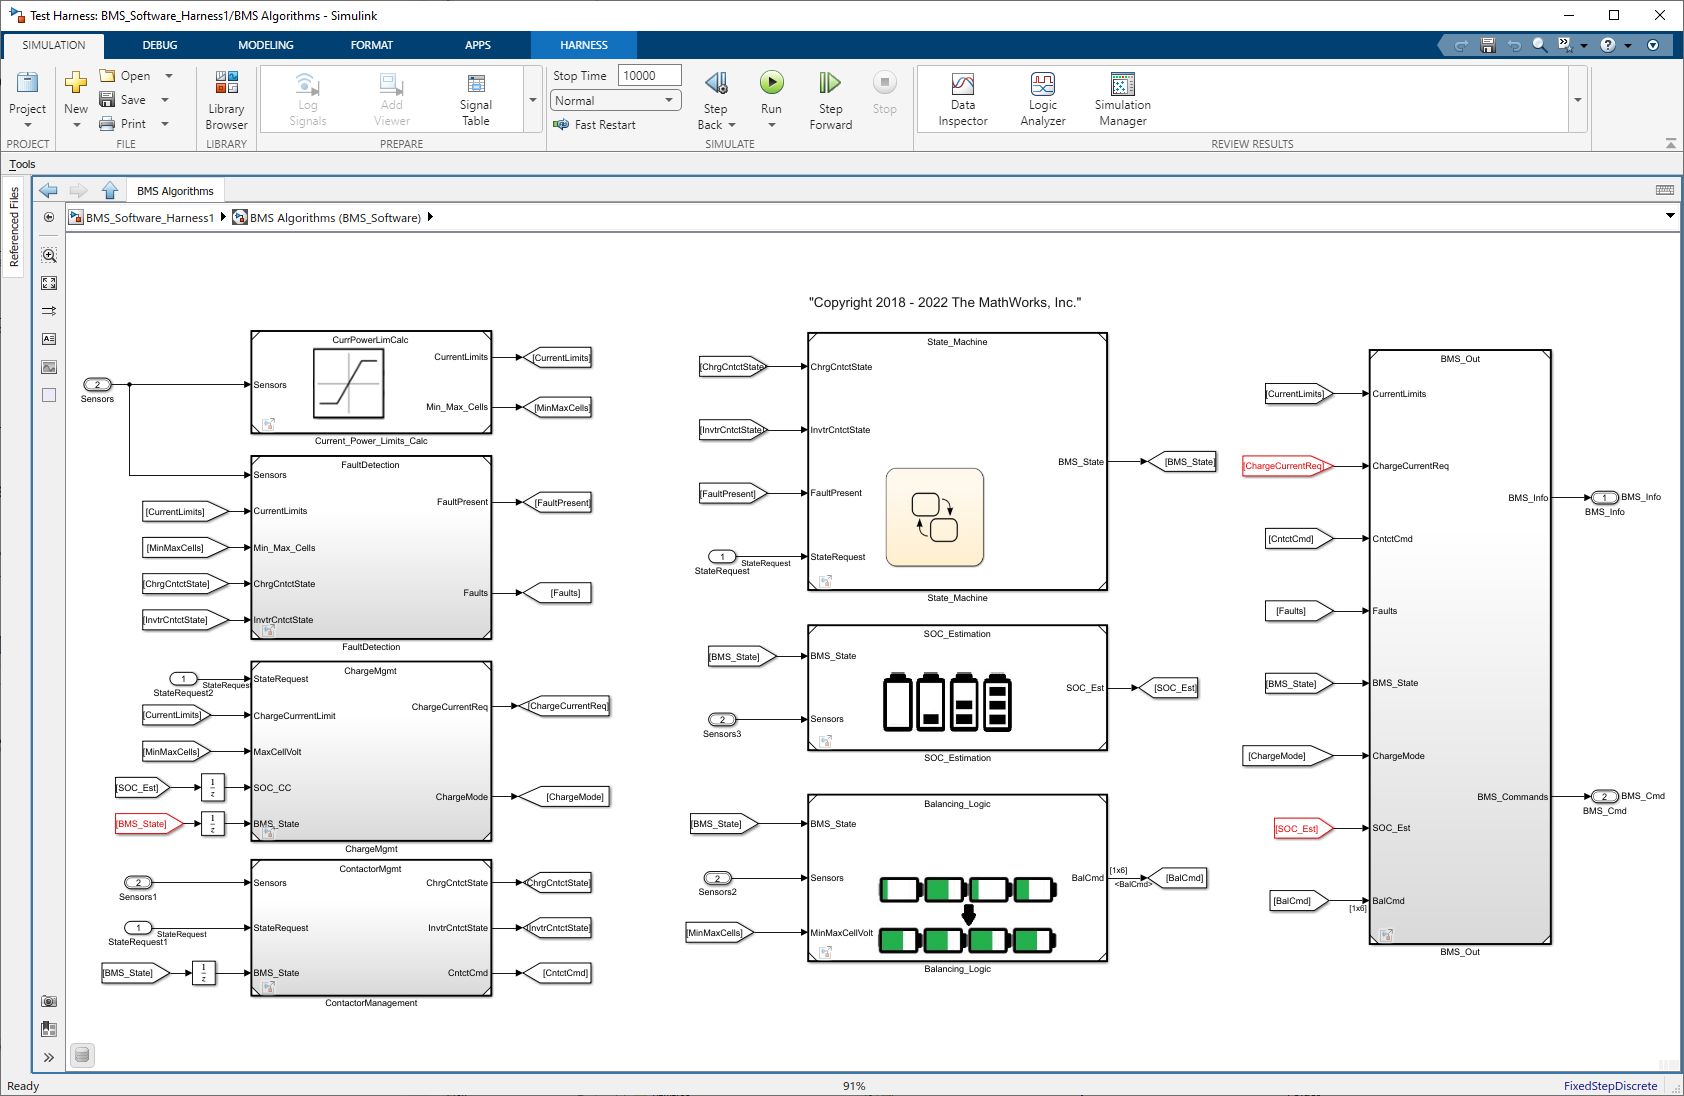

[Run Simulation](matlab:sim('BMS_Software_Harness1');)

Visualize Results 

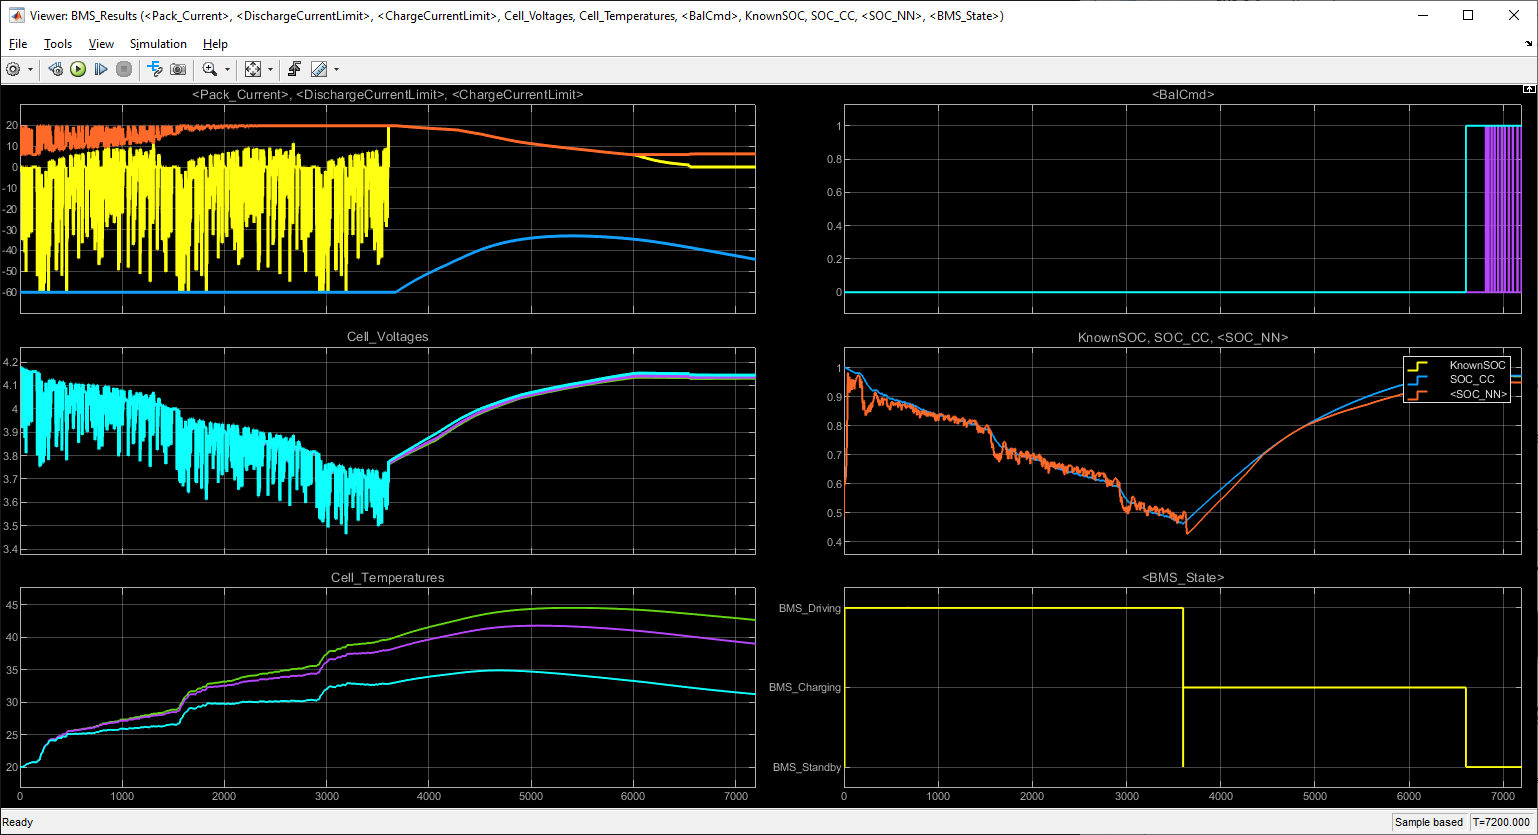

Change Active_Scenario_Index to 2/3 and rerun simulation.

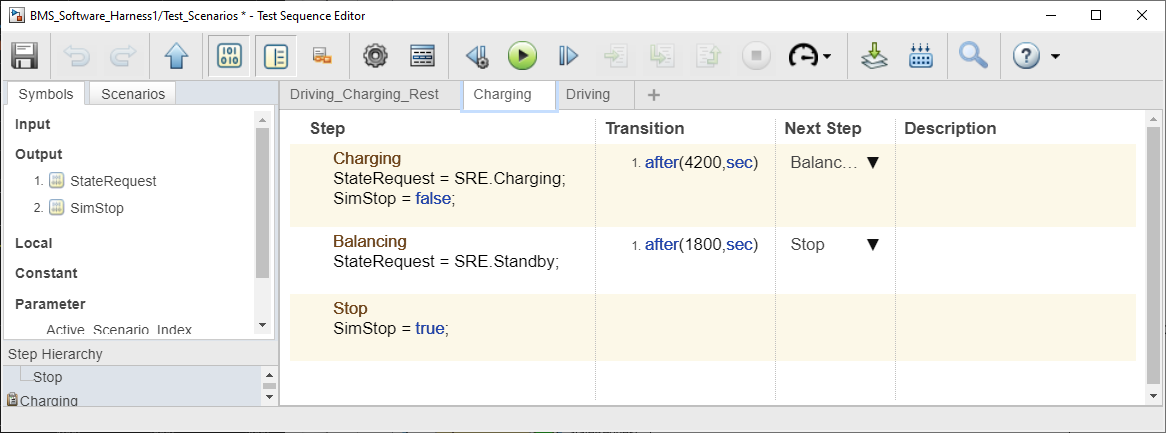

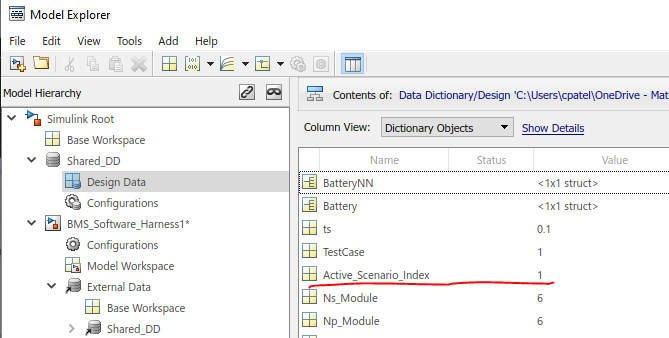

## Generate Floating Point C Code

open_system('BMS_Software'); % Open Model
rtwbuild('BMS_Software'); % Generate Code

### Starting serial model reference code generation build.
### Checking status of model reference code generation target for model 'BMS_Out' used in 'BMS_Software'.
### Model reference code generation target (BMS_Out.c) for model BMS_Out is out of date because BMS_Out.c does not exist.
### Starting build procedure for: BMS_Out
### Invoking custom build hook: CodeGenEntry
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\BMS_Out
### Invoking custom build hook: CodeGenBeforeTLC
### Invoking Target Language Compiler on BMS_Out.rtw
### Using System Target File: C:\Program Files\MATLAB\R2022b\rtw\c\ert\ert.tlc
### Loading TLC function libraries
........
### Initial pass through model to cache user defined code
.
### Caching model source code
.........................................
### Writing header file BMS_Out_types.h
### Writing header file BMS_Out.h
### Writing h

### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\BMS_Out\instrumented\BMS_Out.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: BMS_Out
### Invoking custom build hook: CodeGenExit
### Checking status of model reference code generation target for model 'Balancing_Logic' used in 'BMS_Software'.
### Model reference code generation target (Balancing_Logic.c) for model Balancing_Logic is out of date because Balancing_Logic.c does not exist.
### Starting build procedure for: Balancing_Logic
### Invoking custom build hook: CodeGenEntry
### Generating code and artifacts to 'Model specific' folder structure
### 

### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\Balancing_Logic\instrumented\Balancing_Logic.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: Balancing_Logic
### Invoking custom build hook: CodeGenExit
### Checking status of model reference code generation target for model 'ChargeMgmt' used in 'BMS_Software'.
### Model reference code generation target (ChargeMgmt.c) for model ChargeMgmt is out of date because ChargeMgmt.c does not exist.
### Starting build procedure for: ChargeMgmt
### Invoking custom build hook: CodeGenEntry
### Generating code and artifacts to 'Model specific' folder

### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\CurrPowerLimCalc\instrumented\CurrPowerLimCalc.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: CurrPowerLimCalc
### Invoking custom build hook: CodeGenExit
### Checking status of model reference code generation target for model 'FaultDetection' used in 'BMS_Software'.
### Model reference code generation target (FaultDetection.c) for model FaultDetection is out of date because FaultDetection.c does not exist.
### Starting build procedure for: FaultDetection
### Invoking custom build hook: CodeGenEntry
### Generating code and artifacts t

### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\FaultDetection\instrumented\FaultDetection.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: FaultDetection
### Invoking custom build hook: CodeGenExit
### Checking status of model reference code generation target for model 'SOC_Estimation' used in 'BMS_Software'.
### Model reference code generation target (SOC_Estimation.c) for model SOC_Estimation is out of date because SOC_Estimation.c does not exist.
### Starting build procedure for: SOC_Estimation
### Invoking custom build hook: CodeGenEntry
### Generating code and artifacts to 'Model s

### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\State_Machine\instrumented\State_Machine.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: State_Machine
### Invoking custom build hook: CodeGenExit
### Simulink cache artifacts for 'BMS_Out' were created in 'C:\Users\cpatel\Downloads\BatteryManagementSystem\work\BMS_Out.slxc'.
### Simulink cache artifacts for 'Balancing_Logic' were created in 'C:\Users\cpatel\Downloads\BatteryManagementSystem\work\Balancing_Logic.slxc'.
### Simulink cache artifacts for 'ChargeMgmt' were created in 'C:\Users\cpatel\Downloads\BatteryManagementSystem\work\Charge

### Invoking custom build hook: CodeGenBeforeTLC
### Invoking Target Language Compiler on BMS_Software.rtw
### Using System Target File: C:\Program Files\MATLAB\R2022b\rtw\c\ert\ert.tlc
### Loading TLC function libraries
.........
### Generating TLC interface API for custom data
.
### Initial pass through model to cache user defined code
..
### Caching model source code
...............................................................
### Writing header file BMS_Software_types.h
.
### Writing header file Min_Max_Cells.h
### Writing header file Fault_Bus.h
### Writing header file BMS_Software.h
### Writing source file BMS_Software.c
.
### Writing header file BMS_Software_private.h
### Writing source file ert_main.c
### TLC code generation complete (took 1.936s).
### Invoking custom build hook: CodeGenAfterTLC
--> Speedgoat after_tlc hook: BMS_Software


### Creating HTML report file index.html
### Saving binary information cache.
### Invoking custom build hook: CodeGenBeforeMake
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\slprj\ert\_sharedutils\instrumented\rtwshared.mk' ...
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\cpatel\Downloads\BatteryManagementSystem\src\BMS_Software_ert_rtw\instrumented\BMS_Software.mk' ...
### Invoking custom build hook: CodeGenAfterMake
### Successful completion of code generation for: BMS_Software
### Invoking custom build hook: CodeGenExit
### Simulink cache artifacts for 'BMS_Software' were created in 'C:\Users\cpatel\Downloads\BatteryManagementSystem\work\BMS_Software.slxc'.

Build Summary

Code generation targets built:

Model              Action           Rebuild R